# EXAMEN

Raúl Correa Ocañas

A01722401

13 de junio de 2023

## Pregunta 3

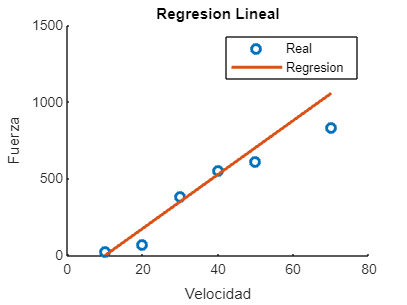

v = [10	20	30	40	50	60	70];
F = [25	70	380	550	610	1220	830];

n = 7;

a1 = (n*sum(v.*F)-sum(v)*sum(F)) / (n*sum(v.^2) - (sum(v)^2));
a0 = mean(F)-a1*mean(v);

reg = @(x) a1*x + a0;

% INCISO A
figure(1)
hold on
index1 = scatter(v,F,"LineWidth",2,"Marker","O");
index2 = plot(v,reg(v),"LineWidth",2);
hold off

legend([index1,index2], "Real", "Regresion");
xlabel("Velocidad")
ylabel("Fuerza")
title('Regresion Lineal')


% INCISO B
a0,a1

a0 = -180.0000

a1 = 17.6607

## Pregunta 7

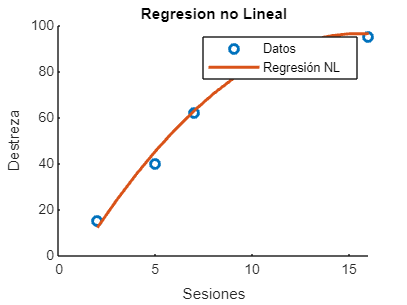

sesiones = [2 5 7 10 12 16];
destreza = [15 40 62 86 92 95];

degree = 2;

p = polyfit(sesiones, destreza, degree);

destreza_fit = polyval(p, min(sesiones):1:max(sesiones));

figure(2)
hold on
a1 = scatter(sesiones, destreza,"LineWidth",2,"Marker","O");
a2 = plot(min(sesiones):1:max(sesiones), destreza_fit,"LineWidth",2);
hold off

legend([a1,a2], "Datos", "Regresión NL")
xlabel('Sesiones')
ylabel('Destreza')
title('Regresion no Lineal')


% Calcular la destreza alcanzada al cabo de 8 sesiones
polyval(p,8)

ans = 70.3718

## Pregunta 8

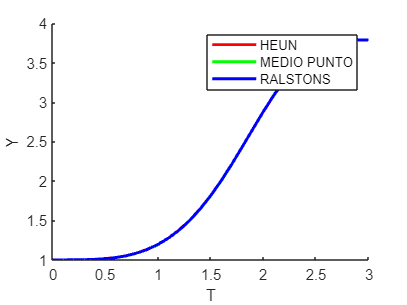

dydx = @(t,y) y*sin(t).^3;
t_1 = 0;
t_f = 3;
y(1) = 1;
dt = 0.1;

% Soluciones a la ecuacion diferenical con cada metodo
[t,y_heun] = Heun(dydx,t_1,t_f, y, dt);
[t,y_mid] = PuntoMedio(dydx,t_1,t_f, y, dt);
[t,y_rals] = Ralston(dydx,t_1,t_f, y, dt);

% Gráficas de los métodos.
figure(3)
hold on
a1 = plot(t, y_heun, 'r', 'LineWidth', 2);    % Heun - rojo
a2 = plot(t, y_mid, 'g', 'LineWidth', 2);     % Medio Punto - verde
a3 = plot(t, y_rals, 'b', 'LineWidth', 2); % Ralston's - azul
hold off

xlabel('T')
ylabel('Y')
legend([a1,a2,a3], 'HEUN', 'MEDIO PUNTO', 'RALSTONS')

## Método de Heun

function [x,y] = Heun(f,t_1,t_f,y,h)
    x = t_1:h:t_f;
    for i = 1:length(x)-1
        k1 = f(x(i), y(i));
        k2 = f(x(i) + h, y(i) + k1*h);
        y(i+1) = y(i) + h*(k1 + k2)/2;
    end
end

## Método de Punto Medio

function [x,y] = PuntoMedio(f,t_1,t_f,y,h)
    x = t_1:h:t_f;
    for i = 1:length(x)-1
        k1 = f(x(i), y(i));
        k2 = f(x(i) + h/2, y(i) + k1*h/2);
        y(i+1) = y(i) + k2*h;
    end
end

## Método de Ralston

function [x,y] = Ralston(f,t_1,t_f,y,h)
    x = t_1:h:t_f;
    for i = 1:length(x)-1
        k1 = f(x(i), y(i));
        k2 = f(x(i) + 3*h/4, y(i) + 3*k1*h/4);
        y(i+1) = y(i) + (k1 + 2*k2)*h/3;
    end
end